*Предмет: Практическая линейная алгебра*

*Автор: Made by Polyakov Anton, the part of R3236, suir family*

*Преподаватель: Алексей Алексеевич Перегудин*

[Source matlab code](https://github.com/GreedlyCore/practice_linear_algebra_labs)

### 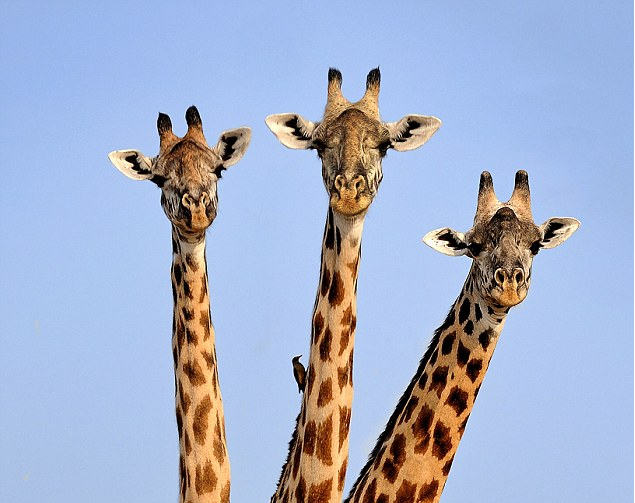

### Содержательная часть

#### Задание 1. Создайте кубик

Vertices = Узлы = Вершины, напоминалочка снизу, я тоже иногда забываю* :)*

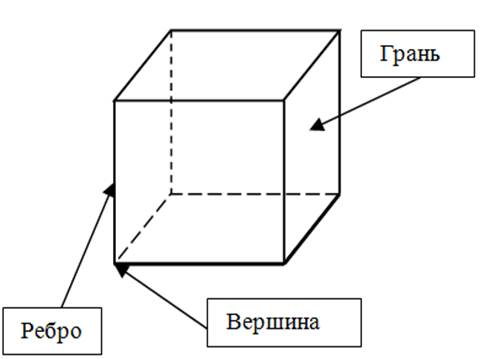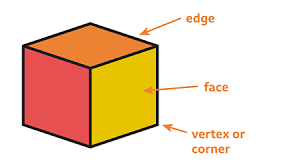

Вектор в этой матрицe без последней компоненты - координаты вершины вида ${\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack }^T$

verticesCube = [
 -1, 1, 1, -1, -1, 1, 1, -1;
 -1, -1, 1, 1, -1, -1, 1, 1;
 -1, -1, -1, -1 , 1, 1, 1, 1;
  1, 1, 1, 1, 1, 1, 1,1
 ];

Face = Плоскости = Грани

Здесь ковекторы задают грани куба, допустим первый ковектор:

$\left\lbrack \begin{array}{cccc}
1 & 2 & 6 & 5
\end{array}\right\rbrack$ - значит, что мы берём из вершин первую, вторую, шестую, пятую строку соответственно, из которых строим плоскость.

*Порядок расположения вершин не имеет значения*

facesCube = [
 1 , 2 , 6, 5;
 2 , 3 , 7, 6;
 3 , 4 , 8, 7;
 4 , 1 , 5, 8;
 1 , 2 , 3, 4;
 5 , 6 , 7, 8
 ];

Строим график, внутри которого используется функция построения 3д фигур, её описание - в приложении

plotCube(1,verticesCube,facesCube,'Оригинальный кубик','g')

Пропорциональный масштаб осей фиксируем, чтобы кубик не уплывал

axis equal;

Установить  позицию рассмотрения графика, "3" = 3D. Дальше функция будет рассмотрена подробнее

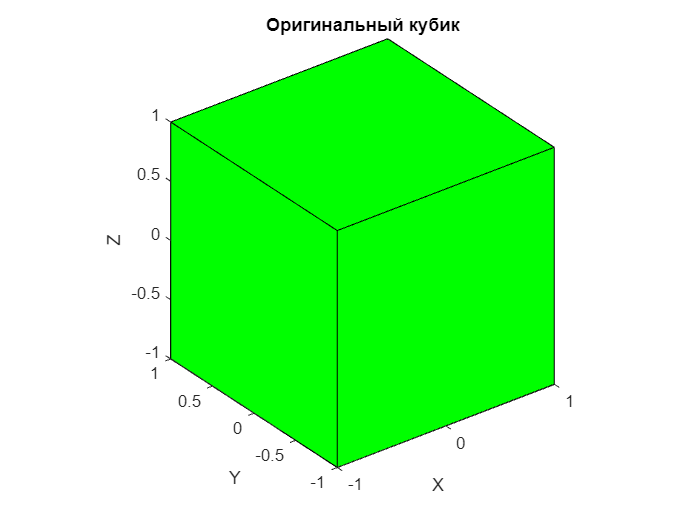

view(3);

Как задать другие фигуры? По правилам выше зададим прямоугольный тетраэдр,

Вершины - $\left\lbrace \left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack ,\right\rbrace$

verticesTriangle = [
 1, 0, 0, 0;
 0, 1, 0, 0;   
 0, 0, 1, 0;
 1, 1, 1, 1;
 ];

С гранями дело немного сложнее, возьмём к примеру вторую плоскость(вторая строка в матрице faces)

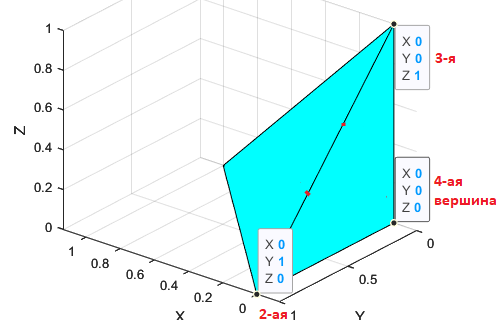

Ищем порядковый номер вершин (смотрим на матрицу вершин, отчет слева направо **от 1**), после записываем в строку матрицы граней в произвольном порядке.

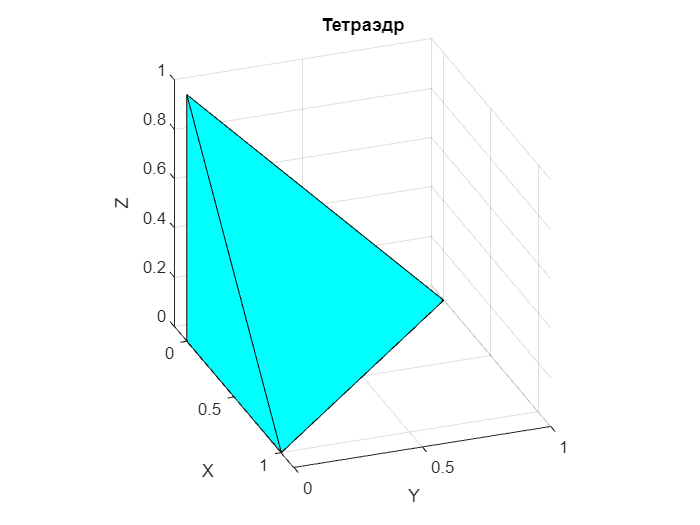

facesTriangle = [
 3, 4, 1; % или 4,1,3 или 1,3,4 - одно и то же
 2, 3, 4;
 4, 1, 2;
 1, 2, 3;
 ];
plotCube(2,verticesTriangle,facesTriangle,'Тетраэдр','cyan')
view([-290.202 25.680])

#### Задание 2. Измените масштаб кубика

Для применения матрицы умножим её слева от матрицы координат вершин кубика.

Почему нельзя использовать матрицы 3х3 мы узнаем в пунктах ниже...

Матрица в общем виде:  $\textrm{Scale}=\;\left\lbrack \begin{array}{cccc}
a & 0 & 0 & 0\\
0 & a & 0 & 0\\
0 & 0 & a & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

Сместим кубики матрицей из третьего задания, чтобы увидеть результат на одном графике

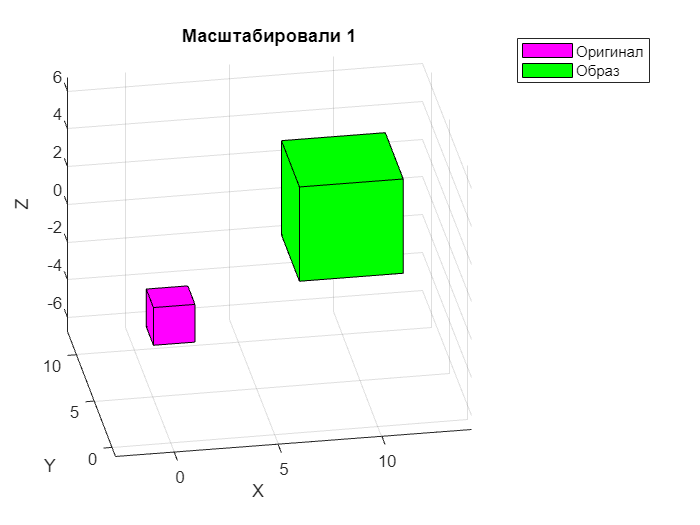

% scaling - параметризованная функция для матриц масштабирования, смотри приложение
% translation - параметризованная функция для матриц перемещения
plotCube2(2222, verticesCube, translation(10,10,0)*scaling(2.5)*verticesCube, ...
    facesCube,'Масштабировали 1')
view([-9.8 26.5])

Попробуем масштабировать на отрицательное значение

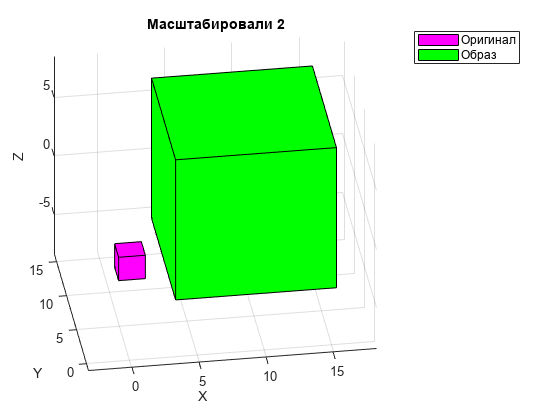

plotCube2(3333, verticesCube, translation(10,10,0)*scaling(-6)*verticesCube, ...
    facesCube,'Масштабировали 2')
view([-8.5 30.5])

#### Задание 3. Переместите кубик

Зададим матрицу преобразования для перемещения кубика. Она не может быть размерности=3, иначе не будет выполняться условия размерностей для выполнения умножения, взгляните:

(3x3)*(4x8) - нельзя матрицы так умножать

(4x4)*(4x8) - можно, тогда будет следующий вид


$$\textrm{translation}*\textrm{vector}=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & {\mathit{\mathbf{T}}}_{\mathit{\mathbf{x}}} \\
0 & 1 & 0 & {\mathit{\mathbf{T}}}_{\mathit{\mathbf{y}}} \\
0 & 0 & 1 & {\mathit{\mathbf{T}}}_{\mathit{\mathbf{z}}} \\
0 & 0 & 0 & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x\\
y\\
z\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x+T_x \\
x+T_y \\
x+T_z \\
1
\end{array}\right\rbrack ,T_i \;-\textrm{соответствующие}\;\textrm{перемещения}\;\textrm{по}\;\textrm{осям}$$


Понятно, что мы игнорируем последнюю компоненту при построении графиков

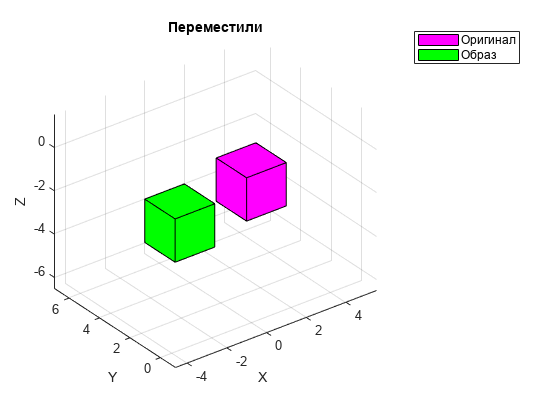

Tx = 1; Ty = 6; Tz = -5;
trans = translation(Tx,Ty,Tz);
plotCube2(5, verticesCube,trans*verticesCube, facesCube,'Переместили')

*Как меняется кубик в зависимости от выбранной комбинации матриц перемещения и масштабирования?*

Иными словами, проверим коммутативность двух комбинаций, на одном графике:

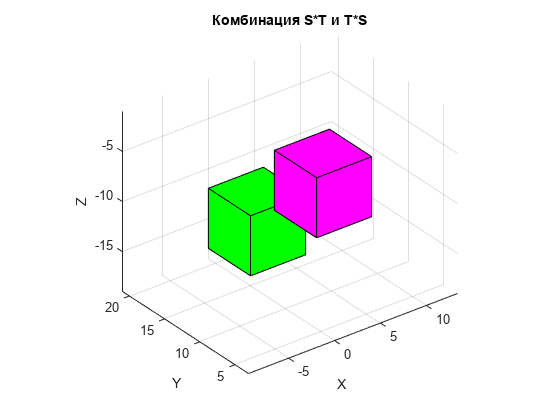

plotCube3(6, (trans*scaling(3))*verticesCube,(scaling(3)*trans)*verticesCube, ...

    facesCube,'Комбинация S*T и T*S')

Так как кубики не слились, значит преобразования не идентичны, следовательно трансформация не коммутативна.

#### Задание 4. Вращаем кубик

*Сколько видов независимых возможных вращений может существовать в 3D пространстве? ****--> 3***

Давайте сначала вспомним обозначение основных трёх вращений

- Крен = Roll = поворот вокруг оси X

- Тангаж = Pitch = Поворот вокруг оси Y

- Рысканье = Yaw = Поворот вокруг оси Z

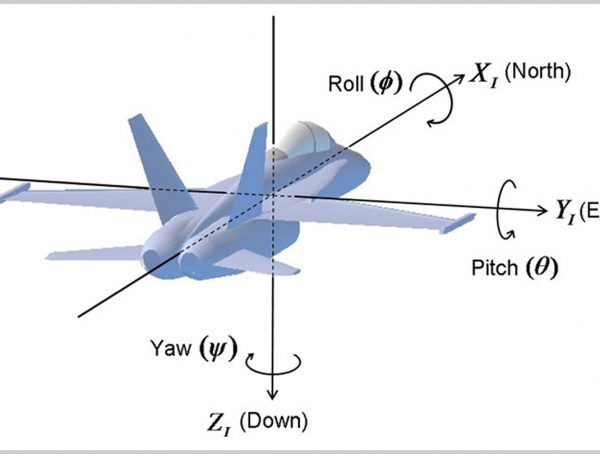

Зададим их матрицы

t=20; % задали угол поворота в градусах
rotationX = [1,   0,        0,     0;
             0, cosd(t), -sind(t), 0;
             0, sind(t), cosd(t),  0;
             0,  0,         0,     1];

rotationY = [cosd(t),  0,  sind(t), 0;
               0,      1,    0,     0;
             -sind(t), 0, cosd(t),  0;
               0,      0,    0,     1];

rotationZ = [cosd(t),  -sind(t),  0,     0;
             sind(t),  cosd(t),   0,     0;
               0,        0,       1,     0;
               0,        0,       0,     1];

Также существуют комбинированные вращения, которые получаются путём умножения двух вращений выше. Учитывая, что перемножение матриц поворота не коммутативно, таких вращений будет существовать 3! = 6 видов. Приведу примеры...

rotationXY = rotationX*rotationY;
rotationYX = rotationY*rotationX;
rotationYZ = rotationY*rotationZ;

Однако мы их не учитываем в итоговом ответе, ведь они являются композицией "базисных" трёх вращений.

Проверим отсутствие коммутативности матриц поворота, построим обе композиции на одном графике

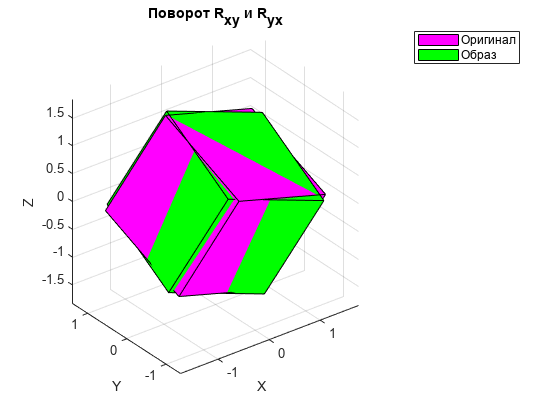

plotCube2(8, rotationXY*verticesCube,rotationYX*verticesCube, ...

    facesCube,'Поворот R_{xy} и R_{yx}')

Наше утверждение верно, ведь фигуры не наложились друг на друга.

Продолжаем, давайте применим один и тот же поворот дважды последовательно:

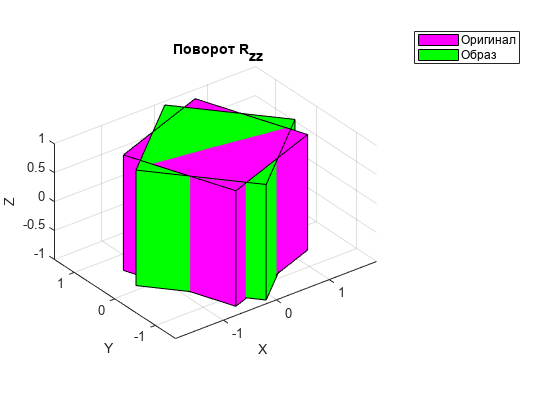

plotCube2(222, rotationZ*verticesCube,(rotationZ*rotationZ)*verticesCube, ...

    facesCube,' Поворот R_{zz}')

*Вспомним прошлую лабу, обладали ли повороты в 2D пространстве свойством коммутативности?*

Да, потому что там можно представить третью ось Z, перпендикулярную осям X,Y. Тогда все вращения в 2D по сути сводились ко вращению  только вокруг оси Z, что делает коммутативность очевидным свойством.

#### [**Задание 5. Выполните вращение кубика около одной вершины**](https://math.stackexchange.com/questions/2093314/rotation-matrix-of-rotation-around-a-point-other-than-the-origin)

Нам нужно сделать вращение кубика таким образом, что центр вращения будет совпадать с одним из его вершин. Получается нам надо сместить точку, относительно которой происходят вращения на одну из вершин единичного куба, пусть этой вершиной станет *(1,1,1)*

Вспомним как выглядит сингулярное разложение матрицы: $A={\mathrm{PDP}}^{-1}$, а ведь здесь происходят похожие вещи - мы переходим в базис собственных векторов, растягиваем как нам надо пространство, возвращаемся назад. В нашем случае - мы перемещаем центр поворотов, выполняем поворот, возвращаемся назад, также $T^{\;-1} \left(x,y\right)=T\left(-x,-y\right)$.

Воспользуемся этой же тактикой, в нашем случае: $B=T\left(x,y\right)*R*T\left(-x,-y\right),\;\mathrm{где}\;T-\mathrm{матрица}\;\mathrm{смещения},R-\mathrm{матрица}\;\mathrm{поворота}$

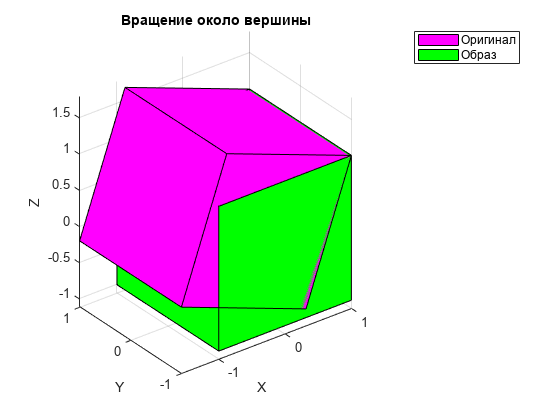

r = translation(1,1,1)*rotationY*(translation(1,1,1)^-1);
plotCube2(11, r*verticesCube,verticesCube, facesCube,'Вращение около вершины')

#### [Задание 6. Реализация камеры](http://www.songho.ca/opengl/gl_camera.html)

В этом задании мы будем активно применять функцию $\textrm{view}\left(\textrm{az},\textrm{el}\right)$, поэтому разберёмся для начала с ней

Два входных аргумента

- az - Azimuth = Азимут

- el - Elevation = Высота 

- или - задать вектор $\left\lbrack \begin{array}{c}
\textrm{cameraX}\\
\textrm{cameraY}\\
\textrm{cameraZ}
\end{array}\right\rbrack$, положение камеры

После задания параметров наша камера будет смотреть **в центр графика** из такой позиции:

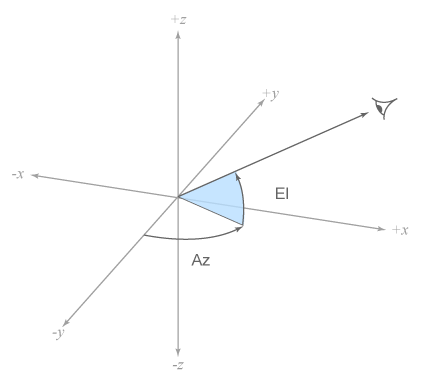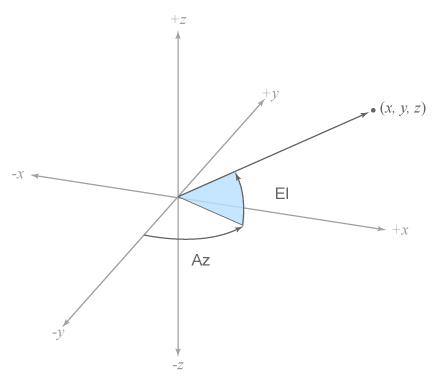

Переформулируем задание - нужно найти матрицу преобразования пространства, которая передвинет сцену так, как если бы двигалась камера.

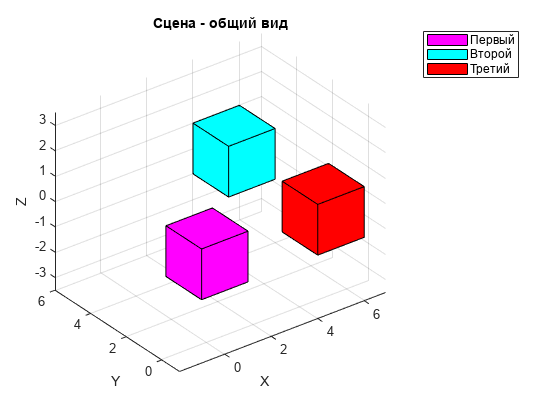

plotCubes(666,verticesCube,facesCube, 'Сцена - общий вид',3,1)

Разобьем задачу на два этапа - нам по сути надо имитировать *передвижение и поворот* камеры.

- Имитация передвижения камеры --> перемещение объектов пространства

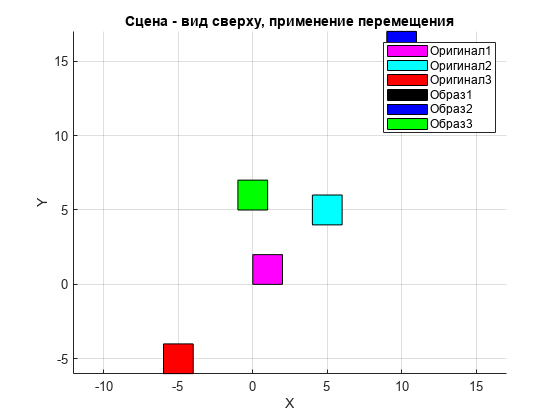

target_X = 5; target_Y = 11; target_Z = -5; % куда сдвигаем пространство
camera_X = 0; camera_Y = 0; camera_Z = 5; % камера просто сверху X,Y

M_trans = translation(target_X,target_Y,target_Z);
plotCubesCompare(787,verticesCube,facesCube, 'Сцена - вид сверху, применение перемещения', ...

    [camera_X, camera_Y, camera_Z],M_trans)

При перемещении кубов на *target *вектор, камера по сути переместиться на *-target*

- Имитация вращения камеры --> вращение пространства относительно точки камеры

Воспользуемся формулой из пятого задания, возьмём для примера вращение вокруг Y, и разместим камеру сбоку

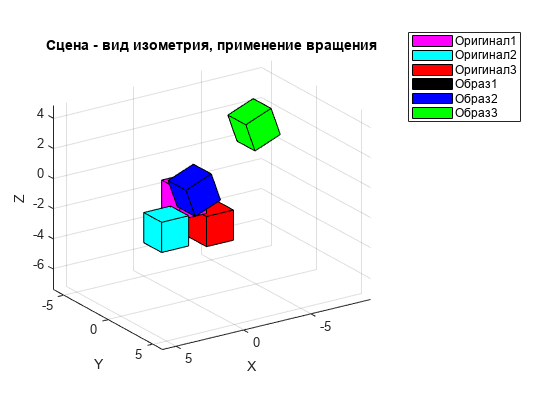

camera_X = 10; camera_Y = 15; camera_Z = 7; % камера "сбоку"
tr = translation(camera_X, camera_Y, camera_Z);
M_rotate = tr*rotationY*(tr^-1);
plotCubesCompare(790,verticesCube,facesCube, 'Сцена - вид изометрия, применение вращения', ...
    [camera_X, camera_Y, camera_Z],M_rotate)

Объединим смещение и поворот: $M_{\textrm{modelView}} =M_{\textrm{rotate}} *M_{\textrm{translation}}$

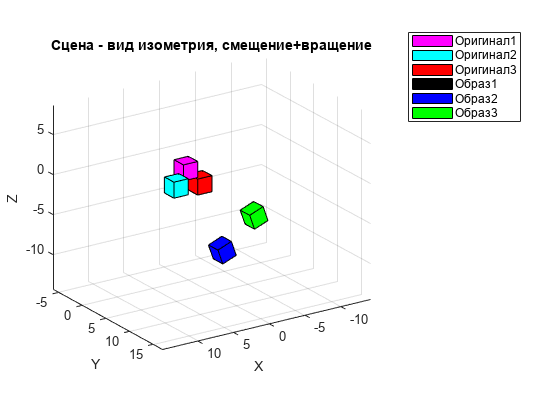

plotCubesCompare(710,verticesCube,facesCube, 'Сцена - вид изометрия, смещение+вращениe', ...
    [camera_X, camera_Y, camera_Z],M_rotate*M_trans)

*Что задает обратная матрица от преобразования? *

- В случае частного случая - только перемещения или только поворота, обратное преобразование в исходную позицию

- В случае перемещения + поворота - давайте взглянем...

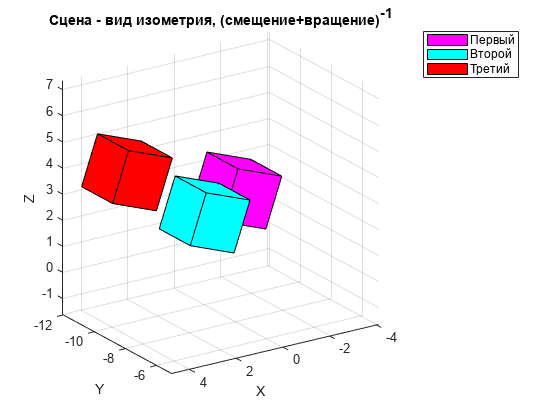

plotCubes(510,verticesCube,facesCube, 'Сцена - вид изометрия, (смещение+вращениe)^{-1}', ...
    [camera_X, camera_Y, camera_Z],(M_rotate*M_trans)^-1)

Кубики явно не вернулись в исходную позицию, можно сделать вывод, в общем случае результат не конкретен и *неизвестен*

#### [Задание 8. Реализация перспективы](https://www.scratchapixel.com/lessons/3d-basic-rendering/perspective-and-orthographic-projection-matrix/building-basic-perspective-projection-matrix.html)

Полный вывод и рассуждения приведены на сайте в заголовке задания и [тут](https://en.wikipedia.org/wiki/3D_projection?useskin=vector#Perspective_projection), здесь мы пройдёмся кратко по материалу

**Добавим перспективу на начальную сцену из шестого задания**

*Как эта матрица устроена? Какие параметры нам необходимо выбрать для её реализации?*

Цель матрицы - проецировать точку на экран "размером" [-1,1] (или NDC space), если она попадает в "объектив" камеры.


$$\textrm{perspective}=\left\lbrack \begin{array}{cccc}
S & 0 & 0 & 0\\
0 & S & 0 & 0\\
0 & 0 & -\frac{f}{\left(f-n\right)} & 0\\
0 & 0 & -\frac{f*n}{\left(f-n\right)} & 0
\end{array}\right\rbrack$$


В простейшем виде можно выбрать $S=1$. 

Первые две компоненты $S$, действуют на x,y , чтобы уместить их в окне камеры, вид окна зависит от **угла** поля зрения камеры(FOV = field-of-view).

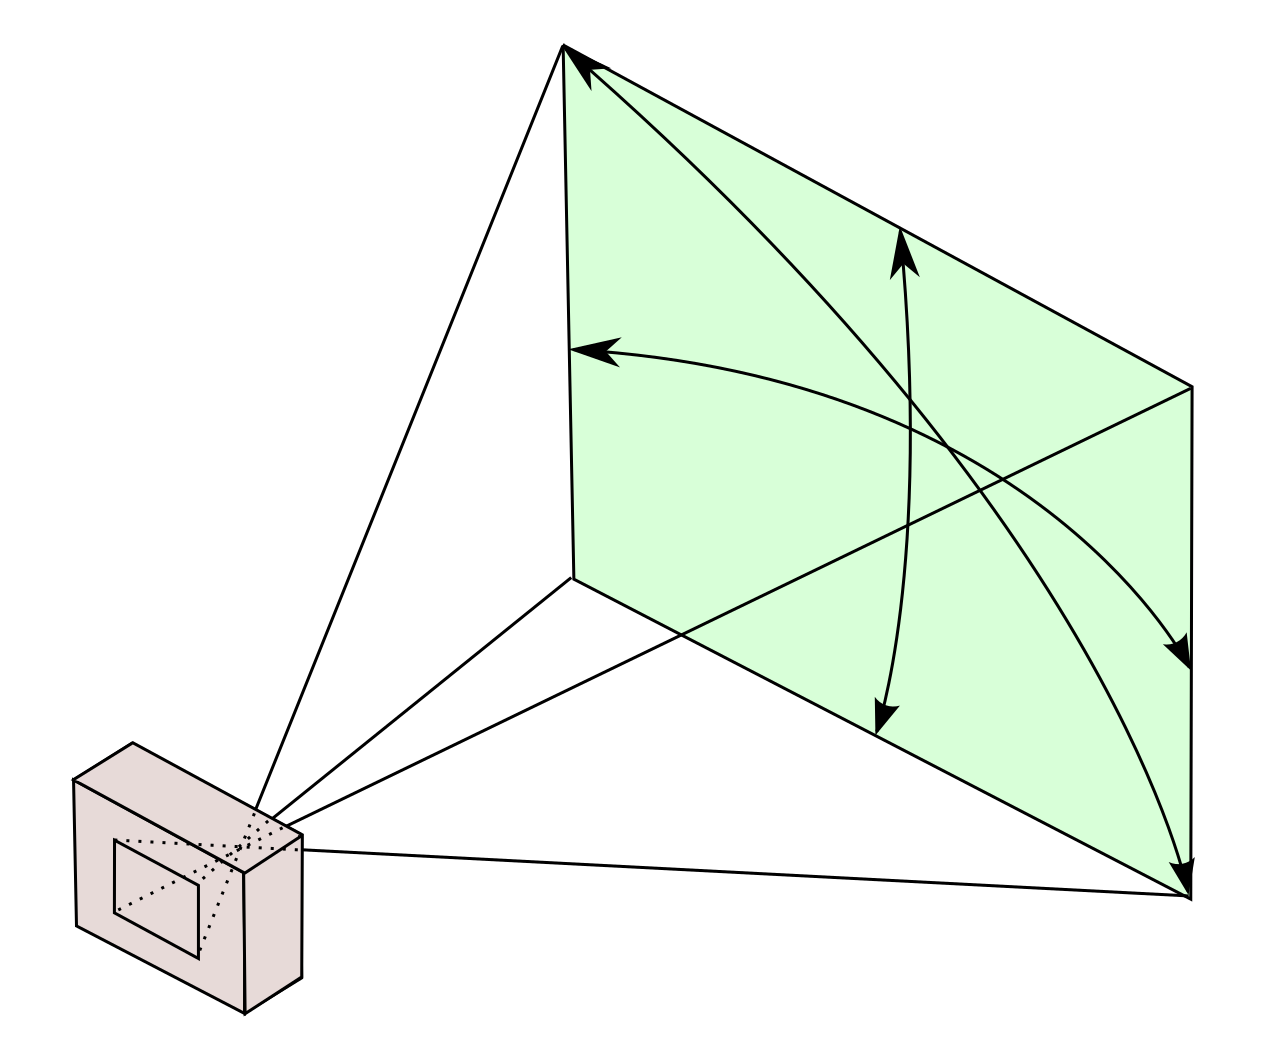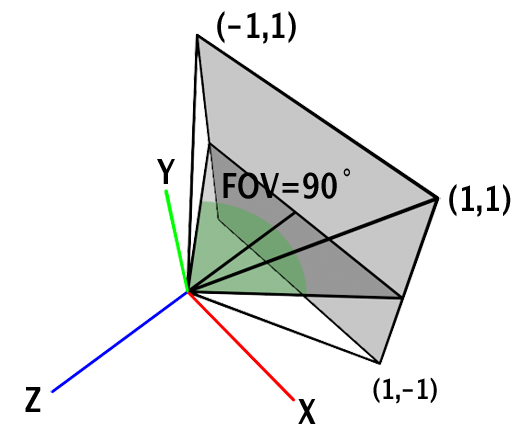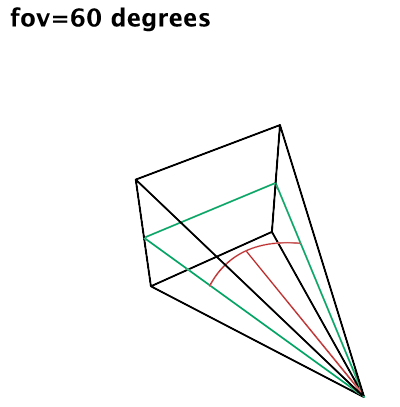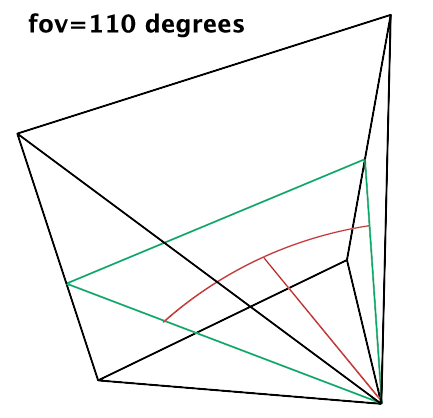

Давайте примерно поймём почему формула именно такая -  $S=\frac{1}{\textrm{tg}\left(\frac{\textrm{FOV}}{2}*\frac{\pi }{180}\right)}$. Нас интересует правильный треугольник, вписанный в конус. Изменение этого угла(красный) между гипотенузой и смежной стороной треугольника определяет длину противоположной стороны треугольника. Поэтому за основу берётся функция тангенса. Обратный тангенс нам приходится его делать из-за того, что при FOV < 90° тангенс даёт значения

< 1, и наоборот, при FOV > 90° нам дают значения > 1,  но ведь нам нужен обратный эффект, потому что приближение должно уменьшать FOV,  поэтому нужно умножить координаты проецируемой точки на значение больше 1, и наоборот.  Внутренности тангенса рассматривать не будем и опустим, чтобы не превратить это задание в пересказ первоисточника.

*Надеюсь вы немного поняли, потому что это и в правду трудно представить без красивой анимации или чтения первоисточника :(*

Расположение следующих $\left(-\frac{f}{\left(f-n\right)},-\frac{f*n}{\left(f-n\right)}\right)$ компонент связано с перемещением координат $x$,$w$ , надеюсь вы не забыли про то как задаются координаты в 3D -${\left\lbrack \begin{array}{cccc}
x & y & z & w
\end{array}\right\rbrack }^T$. При проекции на плоскость мы должны понимать какие точки ближе, а какие - дальше. В этом нам помогает нормализованная координата $z$, которая теперь лежит в таком отрезке $z\to \left\lbrack 0;1\right\rbrack \;\textrm{или}\;\left\lbrack \textrm{близко};\textrm{далеко}\right\rbrack$. Чтобы так нормализовать, как раз пригодится компонента $w$, но все тонкости преобразований мы опустим. 

Но что внутри этих компонент? значение $n$ задаёт самую ближнюю область, откуда начнётся перспектива, напротив $f$- задаст дальнюю (near-clipping and far-clipping plane)

Вспомним старую сцену...

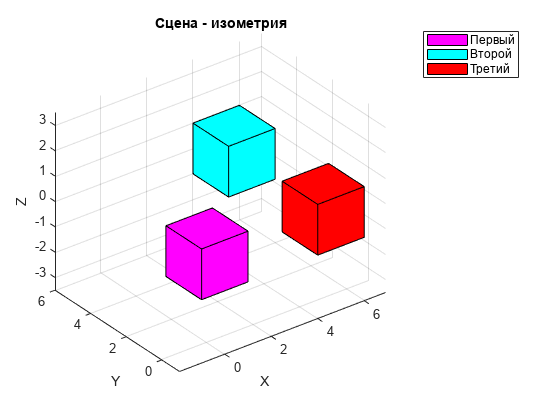

plotCubes(111,verticesCube,facesCube, 'Сцена - изометрия',3,1) 

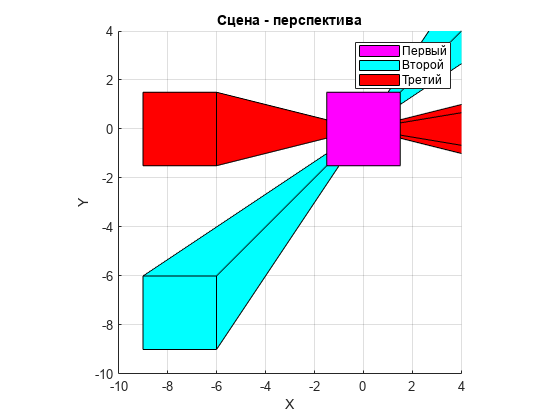

FOV = 90; f=2; n=0.5;
persp = perspective(FOV,f,n);
plotCubes(106,verticesCube,facesCube, 'Сцена - перспектива',[0,0,1], ...
    persp) 
xlim([-10 4])
ylim([-10 4])
zlim([-10 10])

Если попробовать повернуть немного прошлую сцену, то уже получится фильм ужасов, сами судите:

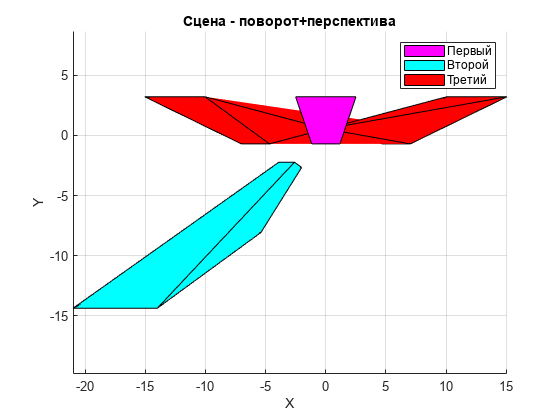

plotCubes(166,verticesCube,facesCube, 'Сцена - поворот+перспектива',[0,0,1], ...
    perspective(90,2,0.5)*rotationX) 

#### [Задание 8. Почти Minecraft](https://www.minecraft.net/ru-ru)

Построим небольшое дерево и посмотрим что можно сделать. Сам процесс построения я сделал путём копирования и смещения одного центрального куба, вынес в отдельную функцию:

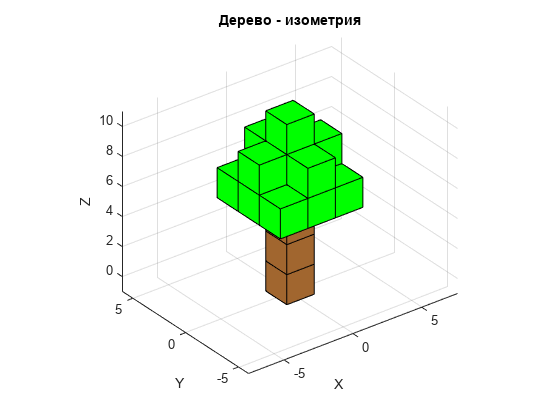

buildTree(190, verticesCube,facesCube,'Дерево - изометрия', 3, 1)

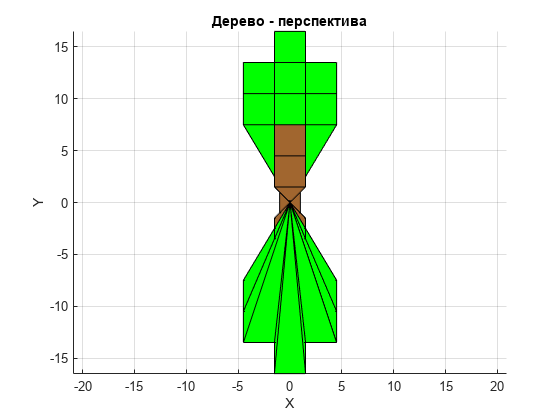

buildTree(1989, verticesCube,facesCube,'Дерево - перспектива', [0 90], persp*rotateX(90))

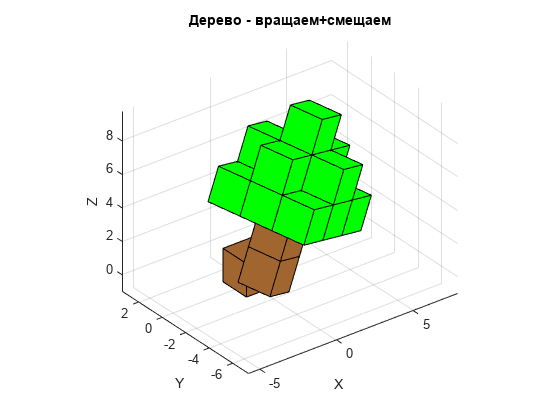

buildTree(2004, verticesCube,facesCube,'Дерево - вращаем+смещаем', ...

    3, translation(-1,-2,-1)*rotationYZ)

Немного подкосило наш мудрый дуб....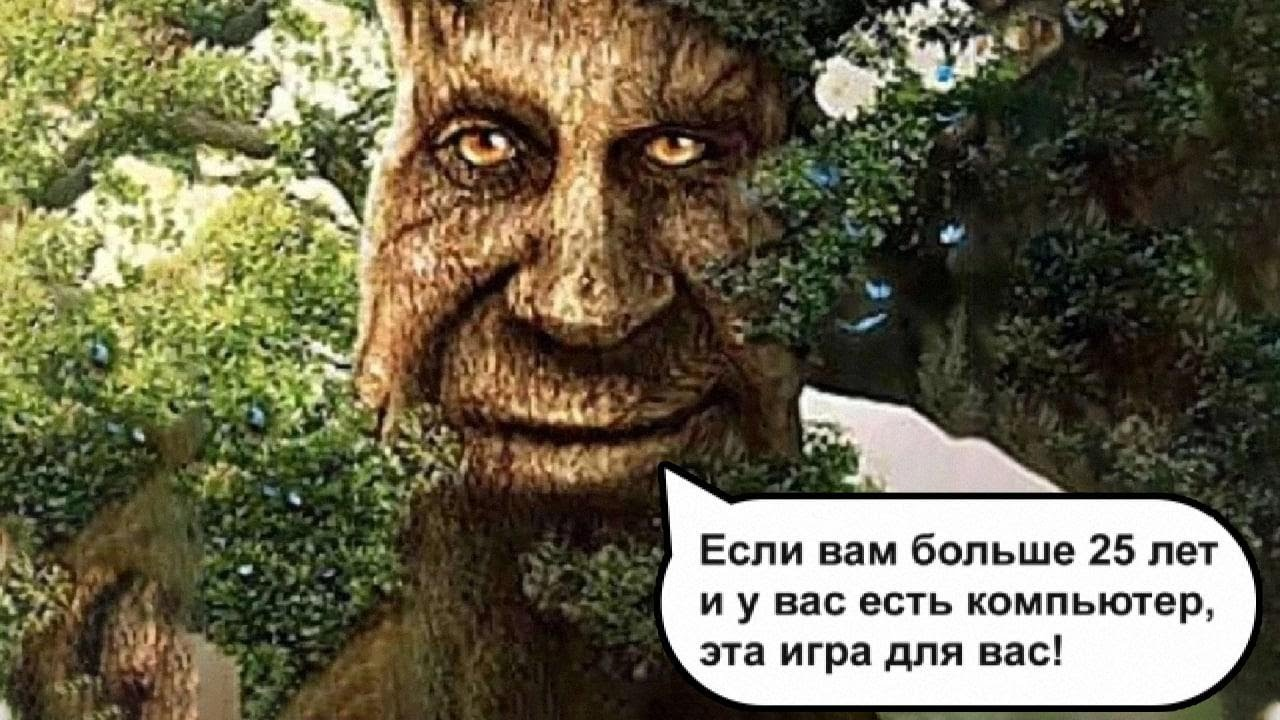

**На сегодня ВСЁ! Спасибо за внимание**

### Вспомогательные функции и их описание

**Построить фигуру из "патчей"**

Апостроф " ' " - транспонирование

" ./ " - поэлементное деление

patch = кусочек, склеиваем фигуру из кусков граней вершин, ребёр 

function DrawShape (vertices ,faces, color )
 patch ('Vertices', ( vertices (1:3 ,:) ./ vertices (4 ,:))', ...
     'Faces', faces,'FaceColor', color) ;
end

**Матрица смещения, но параметризованная**

function result = translation(Tx ,Ty, Tz)
result = [1, 0, 0, Tx;
          0, 1, 0, Ty;
          0, 0, 1, Tz;
          0, 0, 0, 1];
end

**Матрица масштабирования, но параметризованная**

function result = scaling(a)
result = [
    a, 0, 0, 0;
    0, a, 0, 0;
    0, 0, a, 0;
    0, 0, 0, 1];
end

**Матрица перспективы, но параметризованная**

function result = perspective(FOV, f,n)
S = 1/(tan((FOV*pi)/(2*180)));
fn1 = -(f)/(f-n);
fn2 = -(f*n)/(f-n);
result = [
    S, 0,  0,   0;
    0, S,  0,   0;
    0, 0, fn1, -1;
    0, 0, fn2,  0];
end

**Матрица поворота вокруг X, но параметризованная**

function result = rotateX(t)
result = [1,   0,        0,     0;
             0, cosd(t), -sind(t), 0;
             0, sind(t), cosd(t),  0;
             0,  0,         0,     1];
end


**Функция для построения графика фигуры, чтобы не дублировать код много раз**

function plotCube(n, vertices, faces, plot_title,color)
    figure(n)
    DrawShape (vertices, faces, color)
    grid on
    title(plot_title)
    axis equal
    view(3)
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
end

**Копия функции выше, но уже для двух фигур**

function plotCube2(n, vertices1,vertices2, faces, plot_title)
    figure(n)
    DrawShape (vertices1, faces, 'magenta')
    title(plot_title)
    axis equal
    view(3)
    grid on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    hold on
    DrawShape (vertices2, faces, 'g')
    legend('Оригинал','Образ')
    hold off
end

**Копия функции выше, но уже для двух фигур и без легенды**

function plotCube3(n, vertices1,vertices2, faces, plot_title)
    figure(n)
    DrawShape (vertices1, faces, 'magenta')
    title(plot_title)
    axis equal
    view(3)
    grid on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    hold on
    DrawShape (vertices2, faces, 'g')
    hold off
end

**Заготовка начальной сцены для 6-го задания**

% transformation - применение матриц, если этот аргумент = 1, ничего не
% делает
function plotCubes(n, vertices, faces, plot_title, camera, transformation)
    figure(n)
    DrawShape (transformation*vertices, faces, 'magenta')
    title(plot_title)
    axis equal
    view(camera)
    grid on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    hold on
    DrawShape(transformation*translation(5,5,0)*vertices, faces, 'cyan')
    DrawShape(transformation*translation(5,0,0)*vertices, faces, 'r')
    legend('Первый','Второй','Третий')
    hold off
end

**Заготовка для сравнения "до и после"  сцены для 6-го задания**

function plotCubesCompare(n, vertices, faces, plot_title, camera, transformation)
    figure(n)
    DrawShape (translation(1,1,0)*vertices, faces, 'magenta')
    title(plot_title)
    axis equal
    view(camera)
    grid on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    hold on
    DrawShape(translation(5,5,0)*vertices, faces, 'cyan')
    DrawShape(translation(-5,-5,-5)*vertices, faces, 'r')

    DrawShape(transformation*translation(5,5,0)*vertices, faces, 'black')
    DrawShape(transformation*translation(5,5,0)*vertices, faces, 'b')
    DrawShape(transformation*translation(-5,-5,-5)*vertices, faces, 'g')
    legend('Оригинал1','Оригинал2','Оригинал3','Образ1','Образ2','Образ3')
    hold off
end

**Строим дерево**

function buildTree(n, vertices, faces, plot_title, camera, transformation)
    figure(n)
    % wood
    DrawShape(vertices, faces, [0.631 0.4 0.184])
    title(plot_title)
    axis equal
    view(camera)
    grid on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    hold on
    DrawShape(transformation*translation(0,0,2)*vertices, faces, [0.631 0.4 0.184])
    DrawShape(transformation*translation(0,0,4)*vertices, faces, [0.631 0.4 0.184])
    % first layer of grass
    DrawShape(transformation*translation(0,0,8)*vertices, faces, 'g')
    DrawShape(transformation*translation(0,2,6)*vertices, faces, 'g')
    DrawShape(transformation*translation(-2,0,6)*vertices, faces, 'g')
    DrawShape(transformation*translation(0,-2,6)*vertices, faces, 'g')
    DrawShape(transformation*translation(2,0,6)*vertices, faces, 'g')
    DrawShape(transformation*translation(2,2,6)*vertices, faces, 'g')
    DrawShape(transformation*translation(-2,2,6)*vertices, faces, 'g')
    DrawShape(transformation*translation(2,-2,6)*vertices, faces, 'g')
    DrawShape(transformation*translation(-2,-2,6)*vertices, faces, 'g')
    % second layer of grass
    DrawShape(transformation*translation(0,0,10)*vertices, faces, 'g')
    DrawShape(transformation*translation(0,2,8)*vertices, faces, 'g')
    DrawShape(transformation*translation(-2,0,8)*vertices, faces, 'g')
    DrawShape(transformation*translation(0,-2,8)*vertices, faces, 'g')
    DrawShape(transformation*translation(2,0,8)*vertices, faces, 'g')
    hold off
end